# Inception from GoogLeNet

This is my attempt to build an inception module from GoogLeNet.

Paper: [http://www.cv-foundation.org/openaccess/content_cvpr_2015/papers/Szegedy_Going_Deeper_With_2015_CVPR_paper.pdf](http://www.cv-foundation.org/openaccess/content_cvpr_2015/papers/Szegedy_Going_Deeper_With_2015_CVPR_paper.pdf)

Here is a diagram of what we want to build:

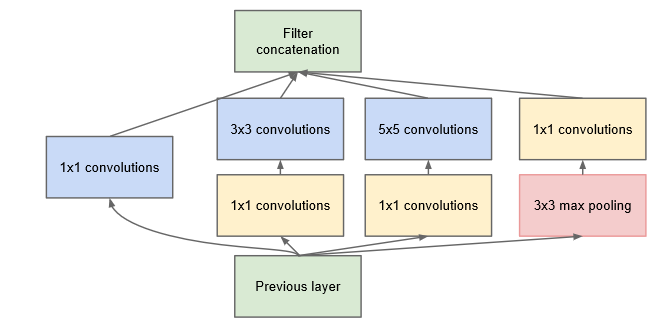

## Create the layers

previous = reluLayer( 'Name', 'input to inception' );

oneByOne = [
    convolution2dLayer( 1, 64, 'Stride', 3, 'Name', '1x1' )
    reluLayer( 'Name', 'relu 1x1')
    ];

threeByThree = [
    convolution2dLayer( 1, 96, 'Name', '3x3 reduce' )
    reluLayer( 'Name', 'relu 3x3_reduce')
    convolution2dLayer( 3, 128, 'Stride', 3, 'Name', '3x3' )
    reluLayer( 'Name', 'relu 3x3')
    ];

fivebyFive = [
    convolution2dLayer( 1, 16, 'Name', '5x5 reduce' )
    reluLayer( 'Name', 'relu 5x5_reduce')
    convolution2dLayer( 5, 32, 'Stride', 3, 'Padding', 1, 'Name', '5x5' )
    reluLayer( 'Name', 'relu 5x5')
    ];

threeMaxPool = [
    maxPooling2dLayer( 3, 'Stride', 3, 'Name', '3x3 pool' )
    reluLayer( 'Name', 'relu 3x3_pool')
    convolution2dLayer( 1, 32, 'Name', '1x1 after pool' )
    reluLayer( 'Name', 'relu 1x1 after pool')
    ];

concat = depthConcatenationLayer( 4, 'Name', 'concat' );

## Add to graph

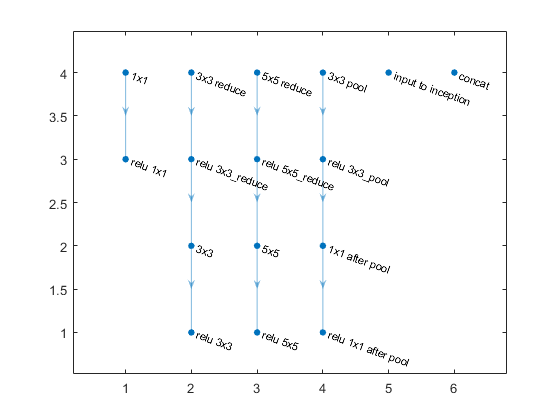

myLayerGraph = layerGraph();
myLayerGraph = addLayers( myLayerGraph, previous );
myLayerGraph = addLayers( myLayerGraph, oneByOne );
myLayerGraph = addLayers( myLayerGraph, threeByThree );
myLayerGraph = addLayers( myLayerGraph, fivebyFive );
myLayerGraph = addLayers( myLayerGraph, threeMaxPool );
myLayerGraph = addLayers( myLayerGraph, concat );
plot( myLayerGraph )

analyzeNetwork( myLayerGraph )

## Connect them up

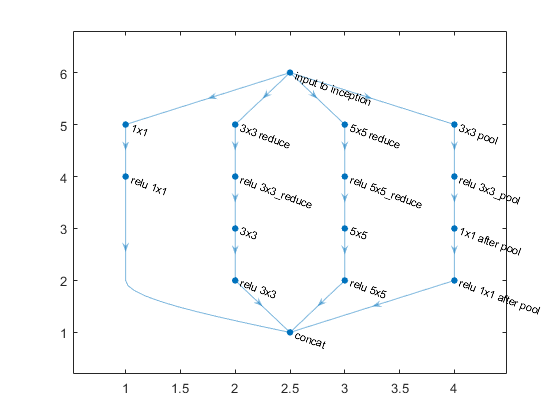

myLayerGraph = localConnectLayers( myLayerGraph, 1, 2 ); % 'input', '1x1' )
myLayerGraph = localConnectLayers( myLayerGraph, 1, 4 ); 
myLayerGraph = localConnectLayers( myLayerGraph, 1, 8 ); 
myLayerGraph = localConnectLayers( myLayerGraph, 1, 12 ); 

myLayerGraph = connectConcatLayer( myLayerGraph, 3, 1 ); 
myLayerGraph = connectConcatLayer( myLayerGraph, 7, 2 ); 
myLayerGraph = connectConcatLayer( myLayerGraph, 11, 3 ); 
myLayerGraph = connectConcatLayer( myLayerGraph, 15, 4 ); 
plot( myLayerGraph )

analyzeNetwork( myLayerGraph )

myLayerGraph

myLayerGraph =   LayerGraph with properties:

         Layers: [16×1 nnet.cnn.layer.Layer]
    Connections: [18×2 table]


## Hook up input & output layers so that we can train it

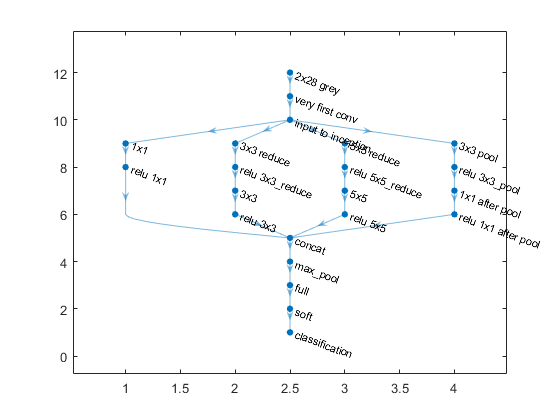

imageSize = [28 28 1];

beforeLayers = [
    imageInputLayer( imageSize, 'Name', '2x28 grey' );
    convolution2dLayer(5,20, 'Name', 'very first conv');
    ];
afterLayers = [
    maxPooling2dLayer(2,'Stride',2, 'Name', 'max_pool');
    fullyConnectedLayer(10, 'Name', 'full' );
    softmaxLayer( 'Name', 'soft');
    classificationLayer( 'Name', 'classification' )
    ];

myLayerGraph = addLayers( myLayerGraph, beforeLayers );
myLayerGraph = addLayers( myLayerGraph, afterLayers );

myLayerGraph = localConnectLayers( myLayerGraph, 18, 1 ); 
myLayerGraph = localConnectLayers( myLayerGraph, 16, 19 ); 
plot( myLayerGraph )

analyzeNetwork( myLayerGraph )

## Training data

We're going use our favorite set of digits

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos',...
    'nndatasets','DigitDataset');
digitData = imageDatastore(digitDatasetPath,...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Split data into training (75%) and validation (25%)

[trainData, validationData] = splitEachLabel( digitData, 0.75 );

Becuase we never have enough data, we are going to augment the images with random rotations

imageAugmenter = imageDataAugmenter( 'RandRotation', [-45 45] );
datasource = augmentedImageSource( imageSize, trainData, 'DataAugmentation', imageAugmenter );

## Training: First run

We're going to some training with a large learning rate.

largeLearningRate = 1e-2;
options = trainingOptions('sgdm',...
    'MaxEpochs', 20, ... % 1
    'Plots', 'training-progress', ...
    'ValidationData', validationData, ...
    'InitialLearnRate', largeLearningRate );

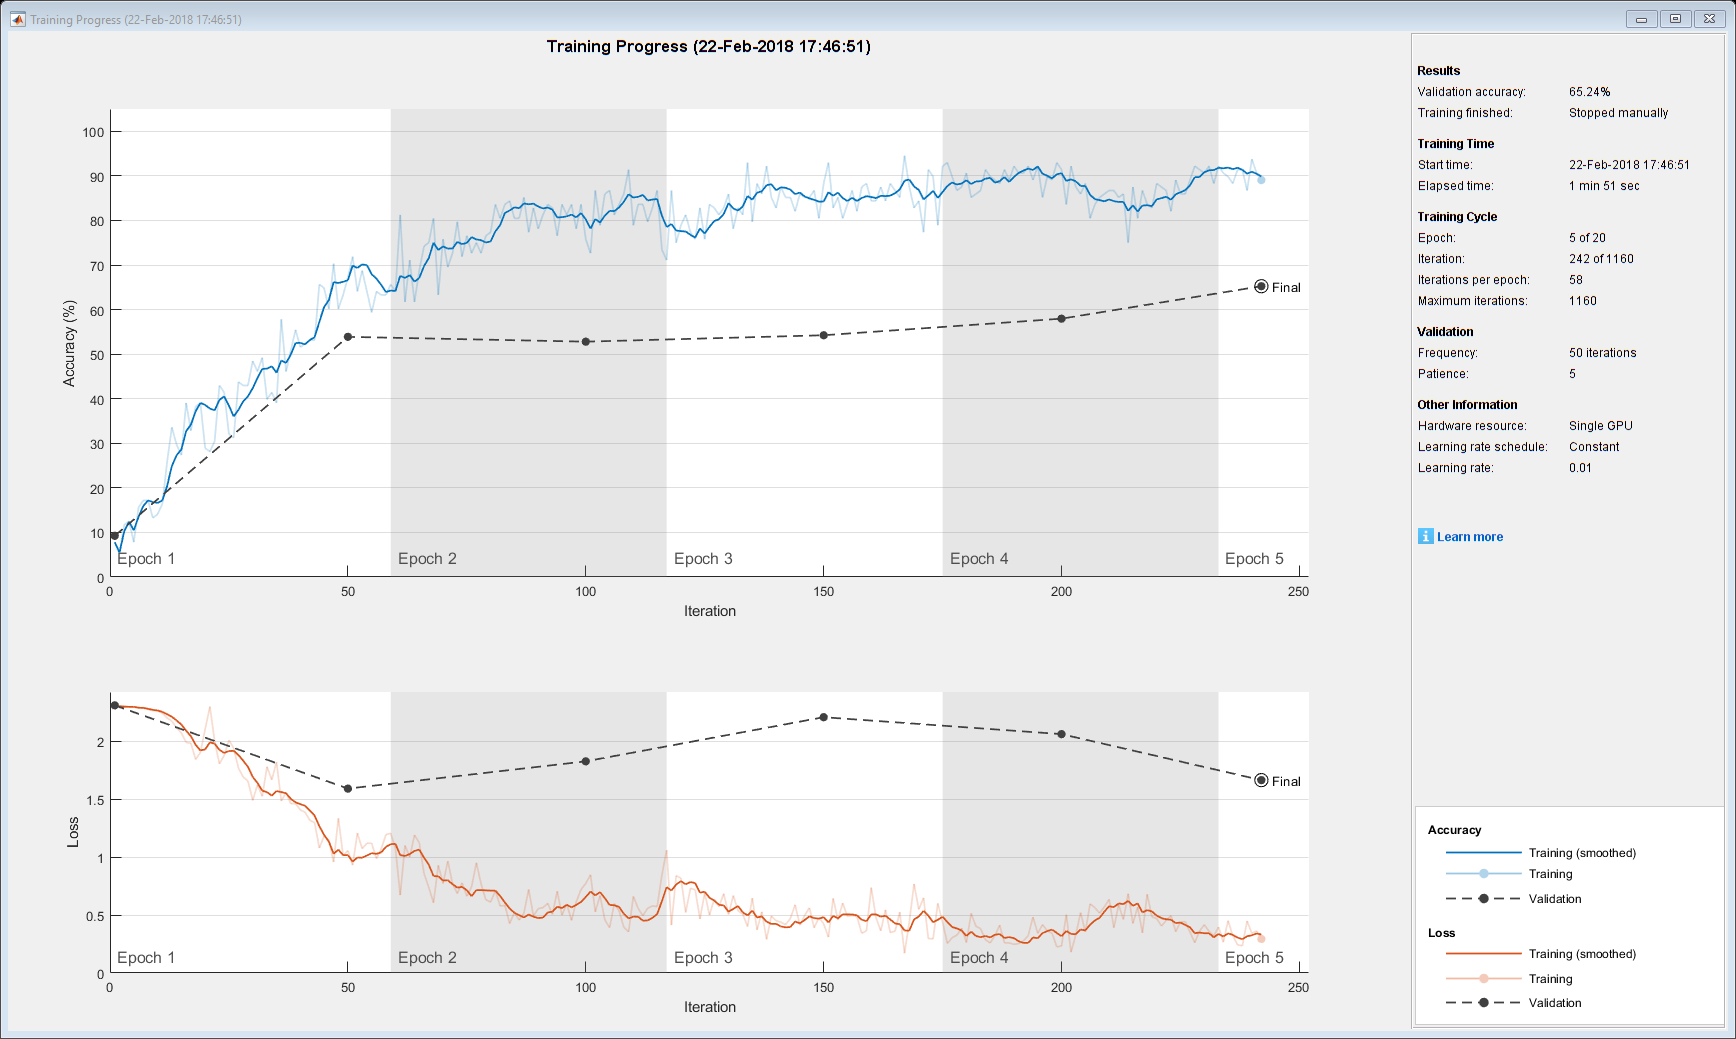

Training on single GPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |        7.81% |        9.24% |       2.3177 |       2.3098 |          0.0100 |
|       1 |          50 |       00:00:27 |       67.19% |       53.88% |       1.0564 |       1.5913 |          0.0100 |
|       2 |         100 |       00:00:49 |       75.78% |       52.80% |       0.7731 |       1.8266 |          0.0100 |
|       3 |         150 |       00:01:08 |       88.28% |       54.24% |       0.4255 |       2.2076 |          0.0100 

notGoogLeNet =   DAGNetwork with properties:

         Layers: [22×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]


notGoogLeNet = trainNetwork(datasource,myLayerGraph,options)

## Training: Second run

For the second training run, we're going to start with what we finished the first training, but use the smaller learning rate to see if we can get to a better model.

resultFromFirstRun = layerGraph( notGoogLeNet );
smallerLearningRate = 1e-4;
options = trainingOptions( 'sgdm',...
    'MaxEpochs', 20, ... % 1
    'Plots', 'training-progress', ...
    'ValidationData', validationData, ...
    'InitialLearnRate', smallerLearningRate );
notGoogLeNet = trainNetwork( datasource, resultFromFirstRun, options );

Training on single GPU.


Initializing image normalization.


This example was originally written to an old API. These functions help with the translation to the new API

function lg = localConnectLayers( lg, from, to )
    from = lg.Layers(from).Name;
    to = lg.Layers(to).Name;
    lg = connectLayers( lg, from, to ); 
end

function lg = connectConcatLayer( lg, from, input )
    from = lg.Layers(from).Name;
    to = "concat/in" + input;
    lg = connectLayers( lg, from, to ); 

end